% preparing the test data
% loading the detector and the ground truth for the test images
load model/trained_yolov4_detector.mat detector
load labeled_data/parkingTestGT.mat parkingTestGT

% creating a combined datastore of the images and bounding box data
[imds, blds] = objectDetectorTrainingData(parkingTestGT);
testData = combine(imds, blds);

% running the data on test images
testResults = detect(detector, testData, "Threshold", 0.5)

testResults = 100×3 table
                    Boxes                        Scores            Labels      
    ______________________________________    ____________    _________________

    {0×4 single                          }    {0×1 single}    {0×1 categorical}
    {0×4 single                          }    {0×1 single}    {0×1 categorical}
    {0×4 single                          }    {0×1 single}    {0×1 categorical}
    {[181.8995 62.1426 127.6039 197.5334]}    {[  0.6879]}    {[EV           ]}
    {[166.3637 47.6040 155.1578 243.0642]}    {[  0.6835]}    {[EV           ]}
    {0×4 single                          }    {0×1 single}    {0×1 categorical}
    {0×4 single                          }    {0×1 single}    {0×1 categorical}
    {[ 198.0176 60.8034 85.5624 201.3844]}    {[  0.8684]}    {[EV           ]}
    {0×4 single                          }    {0×1 single}    {0×1 cate

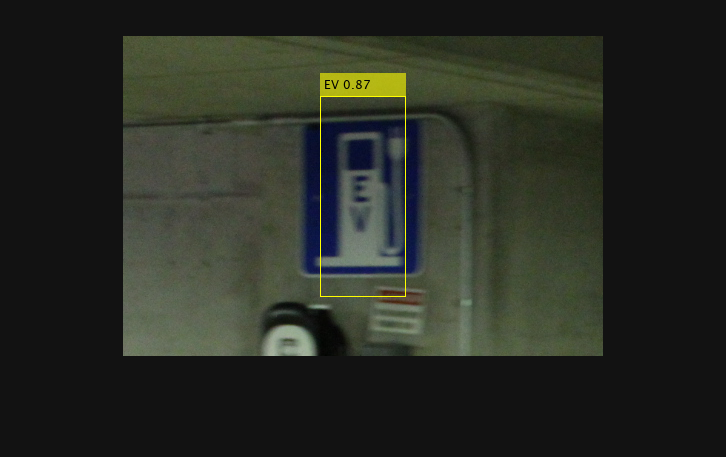

% visualizing detections
numImages = height(testResults);  % to set a limit on the control
imgIdx = 8;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

% evaluating detection results
% setting the IoU threshold. The default value is 0.5
iou = [0.5 0.25];

% evaluating the detector
metrics = evaluateObjectDetection(testResults, testData, iou);

% getting the class names to use later
classNames = metrics.ClassNames;

[datasetSummary, classSummary] = summarize(metrics)

datasetSummary = 1×4 table
    NumObjects    mAPOverlapAvg    mAP0.5     mAP0.25
    __________    _____________    _______    _______

       135           0.3143        0.28491    0.3437 


classSummary = 3×4 table
                  NumObjects    APOverlapAvg     AP0.5       AP0.25 
                  __________    ____________    ________    ________

    Accessible        48           0.27231       0.23482     0.30981
    Charger           29          0.051724      0.034483    0.068966
    EV                58           0.61887       0.58541     0.65233


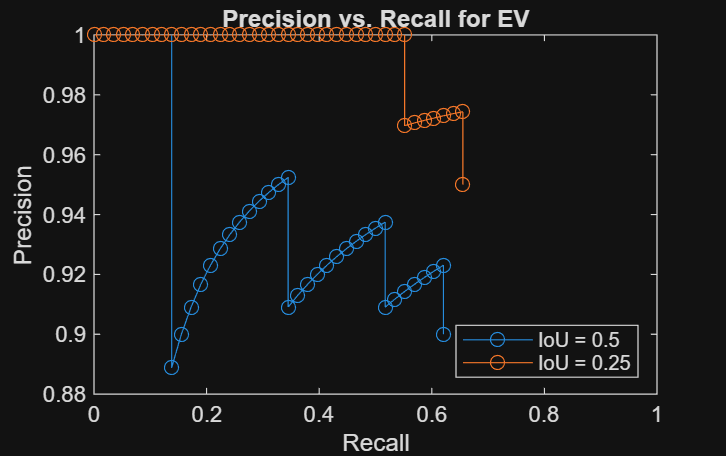

% visualizing precision-recall curves for different classes
[precision, recall, scores] = precisionRecall(metrics);

class = categorical({'EV', 'Charger', 'Accessible'});
class = class(1); % setting default selection to first option (EV)

% plotting precision-recall for IoU 1
plot(recall{class,1}, precision{class,1}, "-o")
xlim([0 1])
xlabel("Recall")
ylabel("Precision")
title("Precision vs. Recall for " + classNames(class))
hold on
% plotting precision-recall for IoU 2
plot(recall{class,2}, precision{class,2}, "-o")
hold off
legend(["IoU = " + iou(1); "IoU = " + iou(2)], "Location", "southeast")

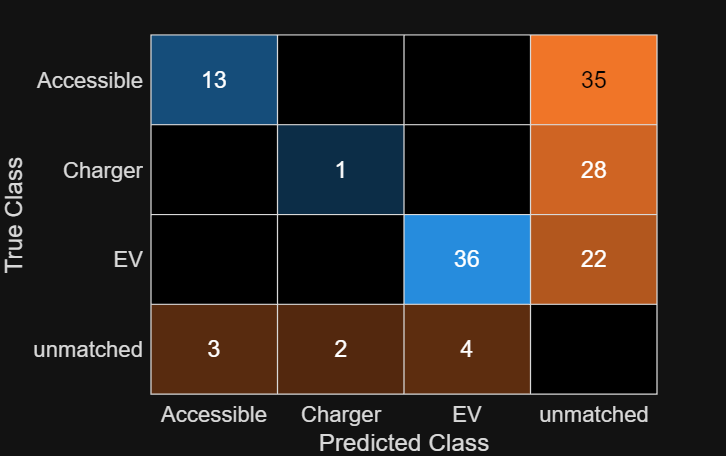

% visualizing the confusion matrix
[cm, confusionClasses] = confusionMatrix(metrics);
confusionchart(cm{1}, confusionClasses)

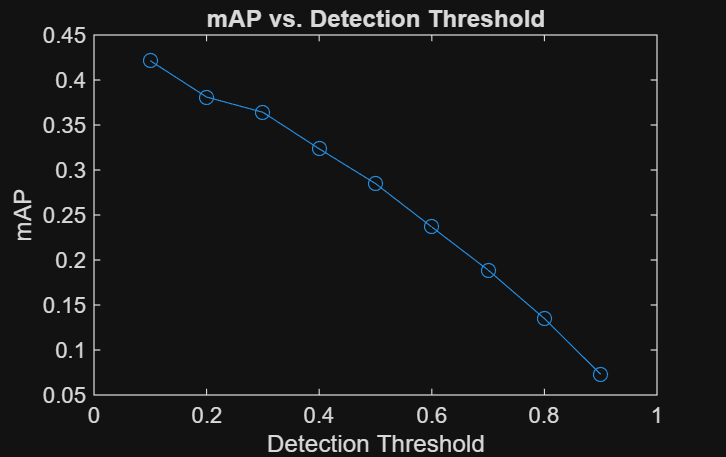

% choosing the best detection threshold
% vector of detection threshold values to test
thresholds = 0.1:0.1:0.9;

% createing a vector to store the results
mAPs = zeros(length(thresholds),1);

% creating a waitbar to monitor progress
f = waitbar(0);

% looping through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    currentMetrics = evaluateObjectDetection(results, testData, iou);
    datasetSummary = summarize(currentMetrics);
    mAPs(ii) = datasetSummary{:, "mAP0.5"};
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% visualizing the mAP vs detection threshold curve
plot(thresholds, mAPs, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")